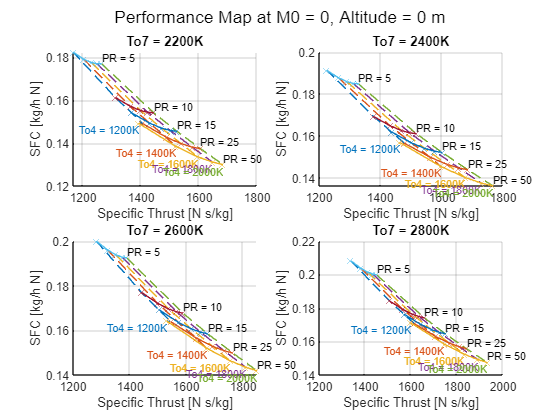

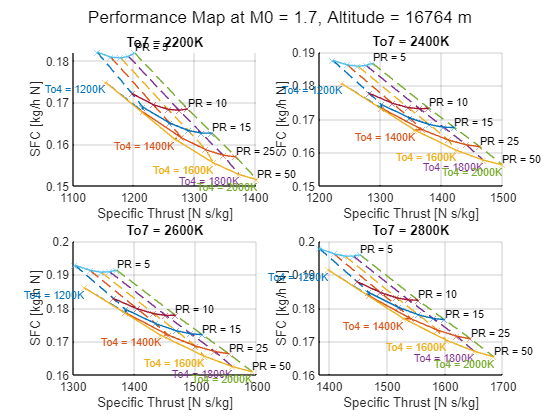

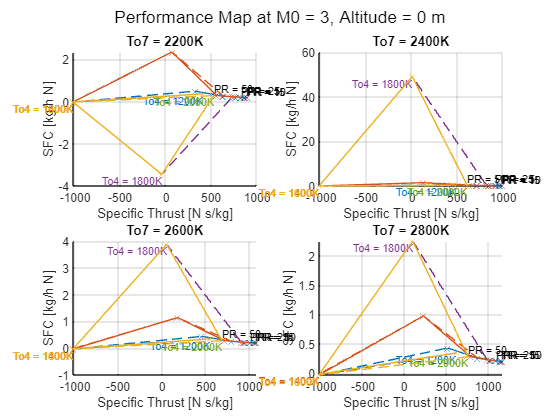

clear; clc; close all;

% Define constants
Gc = 7/5; Gh = 4/3; R = 287; dHB = 4.3e7; % unit: J/kg
To4 = [1200, 1400, 1600, 1800, 2000]; % Turbine inlet temperatures, unit: K
PR = [5, 10, 15, 25, 50]; % Pressure ratios
beta = [0.5, 2, 4, 8]; % Bypass ratios
To7 = [2200, 2400, 2600, 2800, 3000]; % AB inlet temperatures, unit: K

% Conditions for each figure
conditions = [0, 0;  1.7, 16764; 3, 0]; % Each row: [M0, H (m)]5, 24384;

for c = 1:size(conditions, 1)
    M0 = conditions(c, 1);
    H = conditions(c, 2);

    % Get atmospheric properties
    [T0, a0, P0, rho0] = atmosisa(H);

    % Create a figure
    figure;
    hold on;
    sgtitle(sprintf('Performance Map at M0 = %g, Altitude = %g m', M0, H)); % Main title with M0 and H
    colors = lines(length(To4));

    % Loop over different beta values
    for k = 1:length(beta)
        subplot(2, 2, k);
        grid on;
        hold on;

        % Compute performance metrics for current beta
        %[SFC, ST] = idealengine(beta(k), 0, To4, PR, P0, T0, M0, dHB, Gc, Gh, R);
        [SFC, ST] = idealengine(0, To7(k), To4, PR, P0, T0, M0, dHB, Gc, Gh, R);

        % Plot lines for constant To4
        for j = 1:length(To4)
        plot(ST(:, j), SFC(:, j), '--', 'Color', colors(j, :), 'DisplayName', ['To4 = ' num2str(To4(j)) 'K, \beta = ' num2str(beta(k))]);
        % Labeling To4 at the start of each curve
        text(ST(end, j), SFC(end, j), ['To4 = ' num2str(To4(j)) 'K'], ...
            'VerticalAlignment', 'top', 'HorizontalAlignment', 'right', ...
            'Color', colors(j, :), 'FontSize', 8);
        end
    
        % Plot lines for constant PR
        for i = 1:length(PR)
            plot(ST(i, :), SFC(i, :), 'Marker', 'x', 'DisplayName', ['PR = ' num2str(PR(i)) ', \beta = ' num2str(beta(k))]);
            % Labeling PR at the end of each curve
            text(ST(i, end), SFC(i, end), ['PR = ' num2str(PR(i))], ...
                'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'FontSize', 8);
        end

        xlabel('Specific Thrust [N s/kg]');
        ylabel('SFC [kg/h N]');
        %title(['\beta = ' num2str(beta(k))], 'FontSize', 10);
        title(['To7 = ' num2str(To7(k)) 'K'] , 'FontSize', 10);
        hold off;
    end

    legend('off');
    hold off;
end

CP

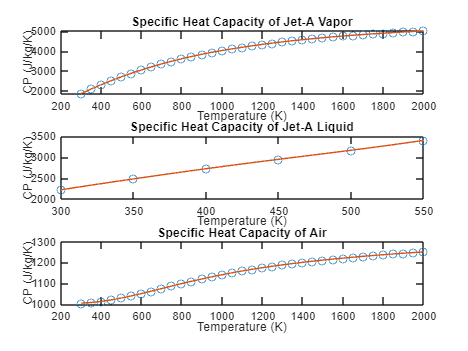

clear; clc; close all;

% Load data
data = readtable('C:\Users\SJ Chen\OneDrive - purdue.edu\Purdue\2024Fall\AAE538 Air-Breathing Propulsion\Project\Specificheat.csv'); 

T = data.T;   % Temperature in K
CPJ8g = data.CPJ8g; % Specific heat of Jet-A vapor in J/kg/K
CPJ8L = data.CPJ8L; % Specific heat of Jet-A liquid in J/kg/K
CPa = data.CPa; % Specific heat of air in J/kg/K

% Create spline representations of the variables
CPJ8g_spline = spline(T, CPJ8g);
CPJ8L_spline = spline(T(~isnan(CPJ8L)), CPJ8L(~isnan(CPJ8L)));  % Use only non-NaN entries
CPa_spline = spline(T, CPa);

% Define a finer temperature range for plotting the splines
T_fine = linspace(min(T), max(T), 300);
T_fine_J8L = linspace(min(T(~isnan(CPJ8L))), max(T(~isnan(CPJ8L))), 300);  % Only within the valid range of CPJ8L

% Evaluate splines on the finer temperature grid
CPJ8g_fine = ppval(CPJ8g_spline, T_fine);
CPJ8L_fine = ppval(CPJ8L_spline, T_fine_J8L);
CPa_fine = ppval(CPa_spline, T_fine);

% Plotting
figure;

% Specific heat of Jet-A vapor
subplot(3,1,1); 
plot(T, CPJ8g, 'o', T_fine, CPJ8g_fine, '-'); 
title('Specific Heat Capacity of Jet-A Vapor'); xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

% Specific heat of Jet-A liquid
subplot(3,1,2); 
plot(T(~isnan(CPJ8L)), CPJ8L(~isnan(CPJ8L)), 'o', T_fine_J8L, CPJ8L_fine, '-'); 
title('Specific Heat Capacity of Jet-A Liquid'); xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

% Specific heat of air
subplot(3,1,3); 
plot(T, CPa, 'o', T_fine, CPa_fine, '-'); 
title('Specific Heat Capacity of Air'); xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

function [SFC, ST] = idealengine(beta, To7, To4, PR, P0, T0, M0, dHB, Gc, Gh, R)
    
    % Define the constants
    Cpc = Gc * R / (Gc - 1); Cph = Gh * R / (Gh - 1);
    Ed = 1; Ec = 1; Eb = 1; Et = 1; En = 1; Eab = 1;
    % Ed = 0.97; Ec = 0.85; Eb = 0.98; Et = 0.91; En = 0.96; Eab = 0.98;
    
    % Preallocate the matrices to store results
    SFC = zeros(length(PR), length(To4));
    ST = zeros(length(PR), length(To4));
    
    T19 = T0;
        
    % station 0
    u0 = M0 * sqrt(Gc * R *T0);
    
    for i = 1:length(PR)
        for j = 1:length(To4)
            % station 2
            To2 = T0 * (1 + (Gc-1)/2 * M0^2);
            Po2 = P0 * (1 + Ed * (Gc-1)/2 * M0^2)^(Gc/(Gc-1));
            
            % station 3
            Po3 = PR(i) * Po2;
            To3 = To2 * (1 + (PR(i)^((Gc-1)/Gc) - 1) / Ec);
            
            % station 4
            Po4 = Po3;
            
            f = (Cph*To4(j) - Cpc*To3) / (Eb*dHB - Cph*To4(j));
            
            % station 5
            M19 = 1; % choke at the nozzle
            To13 = T19 * (1 + (Gh-1)/2 * M19^2);
            
            To5 = To4(j) - (Cpc/Cph)/(1 + f) * ((To3 - To2) - beta*(To13-To2));
            Po5 = Po4 * (1 - ((1 - To5/To4(j)) / Et))^(Gh/(Gh-1));
                        
            % station 7
            Po7 = Po5;
            
            fab = (1+f) * (Cph*To7 - Cpc*To5) / (Eab*dHB - Cph*To7);
            
            % station 9
            u9_f = sqrt(2*Cph*To5*En * ( 1-(P0/Po5)^((Gh-1)/Gh) ));
            u9_ab = sqrt(2*Cph*To7*En * ( 1-(P0/Po7)^((Gh-1)/Gh) ));
            
            % Calculate Specific Thrust and SFC
            if beta ==0
                u9 = u9_ab;
            else
                u9 = u9_f;
                fab = 0;
            end
            
            ST(i, j) = (1+f+fab)/(1+beta)*u9 - 1/(1+beta)*u0 + beta/(1+beta) ...
                * (M19*sqrt(Gc*R*T19) - M0*sqrt(Gc*R*T0));
            SFC(i, j) = (f + fab) / ST(i, j) / (1+beta) * 3600;
        end
    end
    
end